# ENGR20/CSCI20 Midterm

clear, clc, close all;

Instructions:** Please read all of the questions carefully**. There will be a "Functions" section at the bottom of this live-script where you will write the functions needed for each of the problems, and I will provide comments to guide you on where to place functions for each problem within that block. Please do not mess with the problem statements. You CAN alter the starting code if you find it helpful but it must accurately solve the problem. There will be an extra credit problem with a decent amount of walkthrough, so do not let that intimidate you.

To Submit: **Rename file to FirstName_LastName_Midterm.mlx** and submit on Canvas.

## Problem 1

Complete the function ReturnNumbers() which takes one positive integer (endValue) as an input argument. The function should generate an array of integers from 1 to endValue, and from this array return: 

- oddNumbers: an array of odd numbers between 1 and endValue from smallest number to largest number

- evenNumbers: an array of even numbers between 1 and endValue from smallest number to largest number

- reverseNumbers: an array of numbers decreasing from endValue to 1

Note: While arrays are double, the entries will be integer numbers.

**Restriction:** Do not use loops, sort, or if else statements.

**Hint:** Use array indexing to select the required numbers to create odd, even and reverse output arrays.

Ex: Given 

The function ReturnNumbers returns:

`The o`ddNumbers array contains odd numbers in range 1 to 11.

The evenNumbers array contains even numbers in range 1 to 11.

The reverseNumbers array contains numbers from 11 to 1 in decreasing order.

endValue = randi([2 50], 1);
% place your function here:
function [oddNumbers, evenNumbers, reverseNumbers] = ReturnNumbers(endValue)
arr = 1: endValue;

oddNumbers = arr(mod(arr,2) == 1);
evenNumbers = arr(mod(arr,2) == 0);
reverseNumbers = endValue : -1 : 1;

end

[oddNumbers, evenNumbers, reverseNumbers] = ReturnNumbers(endValue)

oddNumbers =      1     3     5


evenNumbers =      2     4     6


reverseNumbers =      6     5     4     3     2     1


## Problem 2

A chemical plant has an input of 10 different materials per day for daily operation. Each input material weighs more than 1 ton and doesn't exceed 100 tons. At the end of the day the weight of all the input materials are added and rounded up for general bookkeeping on material consumption. 

Write a function called MaterialSum() that takes a row array with the weights of 10 materials, calculates the sum of the weights, and then returns the sum. Then, output the returned sum to two decimal places. 

Ex: Given:

`Output: `

weightArray = (1 + (100 - 1)*rand(10,1))';

% enter your function here
function [] = MaterialSum(weightsArray)
    weightSum = sum(weightsArray);
    fprintf('The daily sum of all the materials is %.2f tons', weightSum);
end

MaterialSum(weightArray)

The daily sum of all the materials is 501.13 tons

## Problem 3

Detecting unusual numbers or outliers in a data set is important in many disciplines, because the outliers identify interesting phenomena, extreme events, or invalid experimental results. A simple method to check if a data value is an outlier is to see if the value is a significant number of standard deviations away from the mean of the data set. For example, $X_k$ is an outlier if

where $\mu_X$ is the data set mean, $\sigma_X$ is the data set standard deviation, and *N *is the number of standard deviations deemed significant. 

Assign outlierData with all values in userData that are numberStdDevs standard deviations from userData's mean. Hint: use logical indexing to return the outlier data values.

Ex: If userData is [9, 50, 51, 49, 100 ] and numberStdDevs is 1, then outlierData is [9, 100].

% place your function here. This problem is harder so I am
% giving you the function signature:
% outlierData = getOutliers(userData, numerStdDevs)
function [outlierData] = getOutliers(userData, numberStdDevs)

ans =      9   100


    outlierData = userData(abs(userData - mean(userData)) > std(userData) * numberStdDevs);
end

getOutliers([9, 50, 51, 49, 100], 1)

## Extra Credit

For this extra credit problem, you will be implementing the Monte Carlo integration to evaluate the integral


$$\int_{0}^{1} f(x) \ \mathrm{d}x = \int_{0}^{1} -4x(x-1) \ \mathrm{d}x$$


You can accomplish this with the following steps:

- Set $N$ to be some number between $10^4$ and $10^6$. Then generate x and y as random numbers of size $N \times 1$.

- Create two anonymous functions, one for the function you are integrating, $f(x)$ and one to check if the values are below or above the curve, $g(x,y)$. Plot this curve and the scatter plot of the randomly generated data. As a hint, here is how you write the anonymous function for the data-checking. 

- You will now want to check g < 0 (to see if the points are under the curve). You will want to sum this logical array to get the number of points under the curve. Call this value $N_{in}$.

- Finally, the integral will be the following expression, where $A_{box}$ is the area of the box you are making around the function.

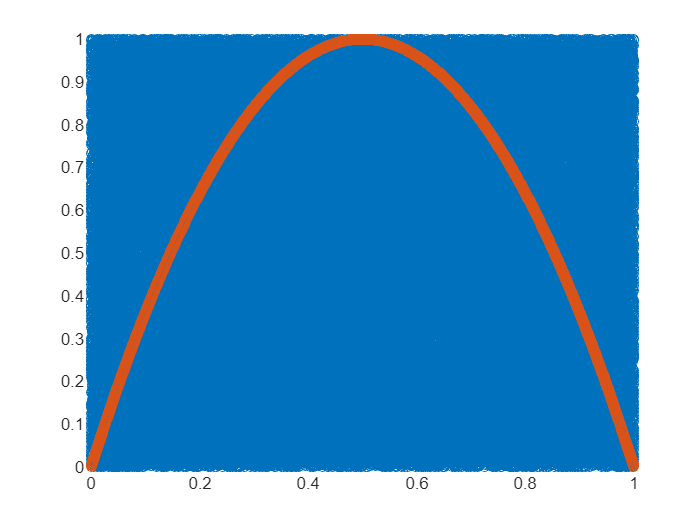

% Enter your code here. Try to break up this code into
% sections like the bulletpoints provided. 
N = 10^5;
x = rand([N,1]);
y = rand([N,1]);

f = @(x) -4 * x .* (x - 1);
g = @(x,y) y - f(x);

scatter(x, y);
hold on;
scatter(x, f(x));
hold off;

values = g(x,y);
N_in = sum(length(values(values < 0)));

A_box = 1;
integral_val = A_box * (N_in)/N

integral_val = 0.6653

% Check
integral(f, 0, 1)

ans = 0.6667

## Functions

% Function for Question 1









% Function for Question 2








% Function for Question 3







% Function for Question 4